%{ 
This script connects to the oscilloscope (R&S - RTB2004) fetches the
signal. It then plots the signal in time domain and plots a spectrogram 
for it in the frequency domain.

Documentation for the remote control commands used are from: 
https://www.rohde-schwarz.com/webhelp/RTB_HTML_UserManual_en/Content/f04d8c7e15c9475d.htm

OUTPUTS:
- Figure:
    - Plot showing signal in time domain as captured from the oscilloscope.
    - Spectrogram showing the tones in the signal
- data_matrix: The signal captured is stored as a matrix the Get Signal
block in the DTMF library uses this variable.

Author: Arundathi Shaji Shanthini
Department of Electrical and Electronic Engineering
University College London 

Last revision: 06/02/2020
%}

## Clear Workspace

clear all;
close all;
warning('off','all');

## Connect to the instrument

% Find a VISA-USB object.
instr_obj = instrfind('Type', 'visa-usb');

% Create the VISA-USB object if it does not exist
% otherwise use the object that was found.
if isempty(instr_obj)
    disp('Error: Rescan for devices using command tmtool!')
    return
else
    fclose(instr_obj);
    instr_obj = instr_obj(1);
end

% Set input buffer size
instr_obj.InputBufferSize=30000000;

% Connect to instrument object
fopen(instr_obj);

## Communicating with the oscilloscope using instrument object, obj1.

%%%%%%% Setup the device for data acquisition %%%%%%%

% Set high resolution mode (16 bit data)
fprintf(instr_obj, 'CHAN:TYPE HRES');
% Set REAL data format 
fprintf(instr_obj, 'FORM REAL');
% Set little endian byte order
fprintf(instr_obj, 'FORM:BORD LSBF');
% Set sample range to memory data in displayed time range
fprintf(instr_obj, 'CHAN:DATA:POIN DMAX');

%%%%%%% Get the signal from oscilloscope %%%%%%%

% Start acquisition
fprintf(instr_obj, 'SIGN');

% Check if operation so far completed succesfully
fprintf(instr_obj,'*OPC?');
OP_status=fscanf(instr_obj,'%c\n',1);
if OP_status == 0
    disp('Error: Setup operation did not complete successfully!')
    return
end

% Clear the buffer
flushinput(instr_obj);

% Read the data
fprintf(instr_obj, 'CHAN:DATA?');

% This returns data in the format: 
% #<number of digits of the following output parameter><number of digits 
% of the following number><value 1><value 2><value 3>....<value n>

% This reads the hash character
hash=char(fread(instr_obj, 1, 'char'));
% This reads the number of digits of the following output parameter
N=str2num(char((fread(instr_obj, 1, 'char'))));     
% This reads the number of data points
num_data_points=str2double(char(fread(instr_obj, N, 'char'))'); 
            
% Note that in the above lines the values were returned as ASCII code
% numbers. Therefore char() was used to get corresponding character before
% it was converted to the required format.

% Get the data
data=fread(instr_obj,num_data_points, 'float32');
data_len=length(data);

% Clear the buffer
flushinput(instr_obj);

% Query the horizontal scale
fprintf(instr_obj,'CHAN:DATA:XINC?');
dt=str2double((char(fread(instr_obj))'));

## Disconnect from the instrument

% Check if operation so far completed succesfully
fprintf(instr_obj,'*OPC?');
OP_status=fscanf(instr_obj,'%c\n',1);
if OP_status == 0
    disp('Error: Setup operation did not complete successfully!')
    return
end

% Close the instrument object, obj1
fclose(instr_obj);

## Defining the time scale values

% Define the time axis values
time=([0:data_len-1].*dt)'; 

% Define the oscilloscope signal as a matrix
% This is the value that Simulink uses
data_matrix=[time(:),data(:)];

## Calculating values for generating frequency domain

% Define Sampling frequency 
Fs= 1/dt; 

% The tones of interest lie between 697Hz and 1477Hz so the frequency range 
% of interest is to be defined as 0-2kHz
F_range = linspace(0,2000,500);

## Plotting the signal and spectrogram

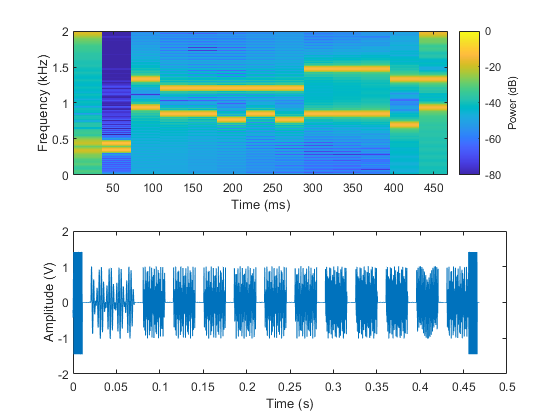

figure;

% Plot the spectrogram (Frequency domain)
subplot(2,1,1);
spectrogram(data,10000,0,F_range,Fs,'yaxis','power')
% Rescaling the colormap to be between only 0dB to 80dB so that colours 
% highlight the peaks better.
caxis([-80 0])

% Plot the signal (Time domain)
subplot(2,1,2);
plot(time,data)
xlabel('Time (s)')
ylabel('Amplitude (V)')